% Loading data
DrivFace = load("data/DrivFace/DrivFace.mat"); % http://archive.ics.uci.edu/ml/datasets/DrivFace

DFdata = DrivFace.drivFaceD.data;
dissimilarities = squareform(pdist(DFdata)); % compute dissimilarity matrix

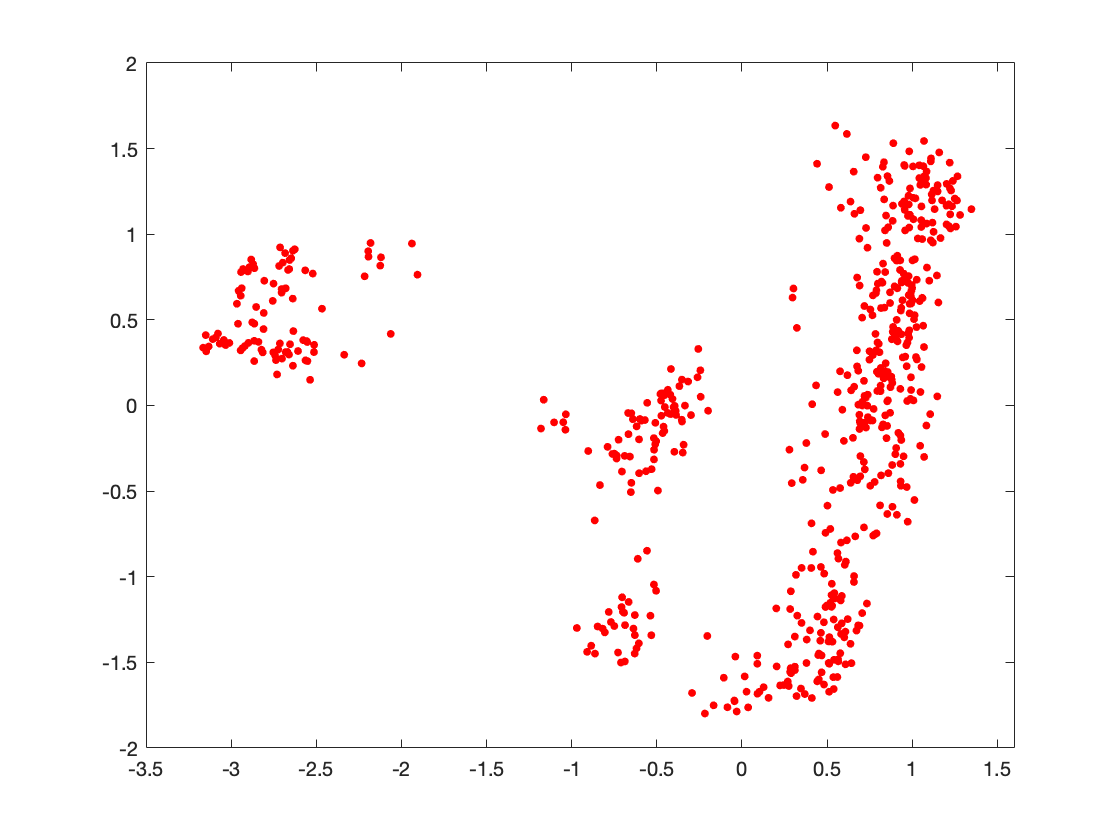

ans =    606   606


% Our implementation
[Y,stress, lambda_p] = cmds(dissimilarities,2); %Q: does not match matlab implementation
figure();
gscatter(Y(:,1),Y(:,2));

fprintf("Total stress s: %f", sum(stress(:))) %Q: this is very high

Total stress s: 61727111669.127548

lambda_p

lambda_p =   978.6935         0
         0  487.0216


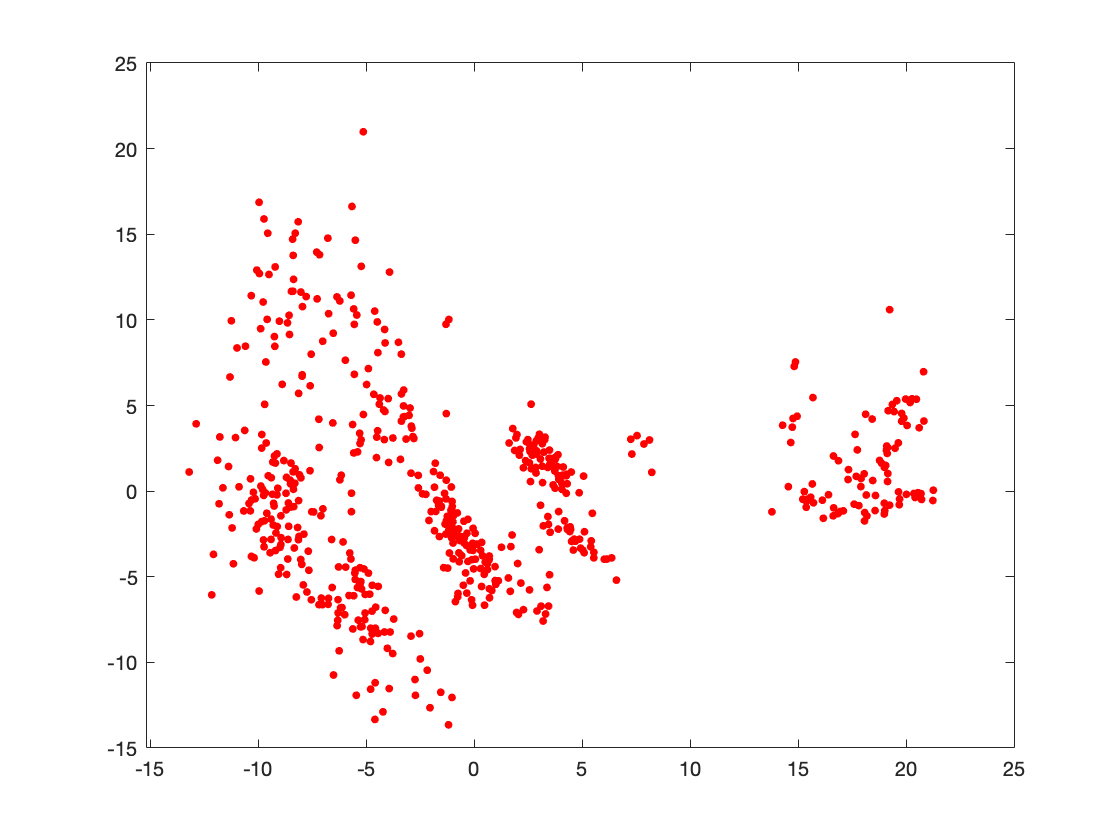

% Matlab implementation
[Y,stress] = mdscale(dissimilarities,2);
figure();
gscatter(Y(:,1),Y(:,2));

fprintf("Total stress s: %f", sum(stress(:)))
lambda_p

function [Y, stress, lambda_p] = cmds(D, p)
    [n,m] = size(D);
    
    % Compute Gram matrix G using double centering
    In = eye(n); % N-by-n dentity matrix
    e = ones(n, 1); 
    part = In - (1/n) * (e * e.');
    G = -0.5 * part * D * part;
    
    % Compute eigenvalues (lambda) and vectors (u) of G Q: left or right?
    [u,lambda] = eig(G); 
    
    % Obtaining p highest eigenvalues and corresponding vectors
    [lambda_p, index_p] = maxk(diag(lambda), p);
    lambda_p = diag(lambda_p).';
    u_p = u(:,index_p);
    
    % For any d compute the coordinates of the points x_i
    Y = (u_p*sqrt(lambda_p));
    
    % Compute stress
    distances = squareform(pdist(Y));
    desired_distances = D;
    stress = (distances-desired_distances)^2; 
end
